# Código Matlab Laboratorio 4

-  Juan Andrés Barrera

- Daniel Felipe Segura

q = sym('q',[1 6]);
T0_1=simplify(MTH(0,sym (pi/2),45,q(1)))

$$T0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 45\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T1_2=simplify(MTH(100,0,0,q(2)))

$$T1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 100\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 100\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T2_3=simplify(MTH((35.5+99),0,0,q(3)))

$$T2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & \frac{269\,\cos\left(q_{3}\right)}{2}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & \frac{269\,\sin\left(q_{3}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3_4=simplify(MTH(45,0,0,q(4)))

$$T3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 45\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 45\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0_TCP=vpa(simplify(T0_1*T1_2*T2_3*T3_4));
x=T0_TCP(1,4),y=T0_TCP(2,4),z=T0_TCP(3,4)

$$x = 0.5\,\cos\left(q_{1}\right)\,\left(90.0\,\cos\left(q_{2}+q_{3}+q_{4}\right)+269.0\,\cos\left(q_{2}+q_{3}\right)+200.0\,\cos\left(q_{2}\right)\right)$$

$$y = 0.5\,\sin\left(q_{1}\right)\,\left(90.0\,\cos\left(q_{2}+q_{3}+q_{4}\right)+269.0\,\cos\left(q_{2}+q_{3}\right)+200.0\,\cos\left(q_{2}\right)\right)$$

$$z = 45.0\,\sin\left(q_{2}+q_{3}+q_{4}\right)+134.5\,\sin\left(q_{2}+q_{3}\right)+100.0\,\sin\left(q_{2}\right)+45.0$$

R = sym('r_%d_%d',3)==T0_TCP(1:3,1:3);
for i=1:numel(R)
disp(R(i))
end

$$r_{1,1}=\cos\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)$$

$$r_{2,1}=\cos\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)$$

$$r_{3,1}=\sin\left(q_{2}+q_{3}+q_{4}\right)$$

$$r_{1,2}=-1.0\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)$$

$$r_{2,2}=-1.0\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)$$

$$r_{3,2}=\cos\left(q_{2}+q_{3}+q_{4}\right)$$

$$r_{1,3}=\sin\left(q_{1}\right)$$

$$r_{2,3}=-1.0\,\cos\left(q_{1}\right)$$

$$r_{3,3}=0$$

q1=0; q2=0; q3=0; q4=0;
T0_TCP = round(subs(T0_TCP),5);
x = T0_TCP(1,4), y = T0_TCP(2,4)    , z = T0_TCP(3,4)

$$x = 279.5$$

$$y = 0$$

$$z = 45.0$$

R=T0_TCP(1:3,1:3)

$$R = \left(\begin{array}{ccc} 1.0 & 0 & 0\\ 0 & 0 & -1.0\\ 0 & 1.0 & 0 \end{array}\right)$$

Gráficas

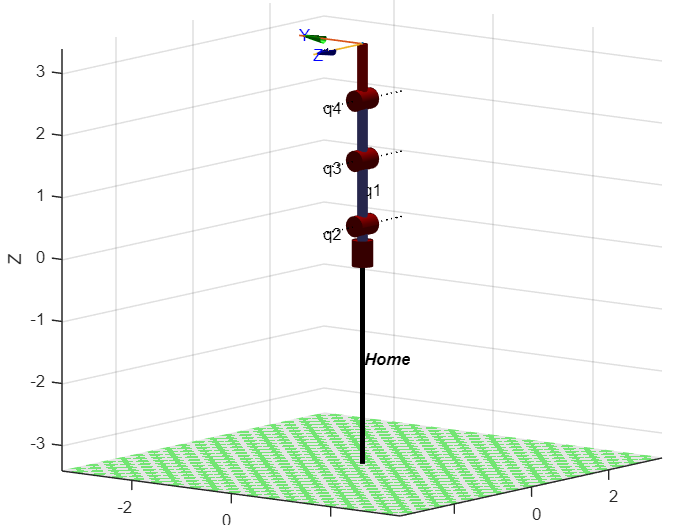


q=[0 pi/2 0 0];


R1 = Link([0 0.45 0 pi/2]);
R2 = Link([pi/2 0 1.054 0]);
R3 = Link([-pi/2 0 0.97 0]);
R4 = Link([0 0 0.90 0]);

M2 = SerialLink([R1; R2; R3; R4], 'name', 'Home');

q1=q+deg2rad([25 25 20 -20]);
R1 = Link([q1(1) 0.45 0 pi/2]);
R2 = Link([q1(2) 0 1.00 0]);
R3 = Link([q1(3) 0 (0.355+0.99) 0]);
R4 = Link([q1(4) 0 0.45 0]);
M2_2 = SerialLink([R1; R2; R3; R4], 'name', 'p1');

q2=q+deg2rad([-35 35 -30 30]);
R1 = Link([q1(1) 0.45 0 pi/2]);
R2 = Link([q1(2) 0 1.00 0]);
R3 = Link([q1(3) 0 (0.355+0.99) 0]);
R4 = Link([q1(4) 0 0.45 0]);
M2_3 = SerialLink([R1; R2; R3; R4], 'name', 'p2');

q3=q+deg2rad([85 -20 55 25]);
R1 = Link([q1(1) 0.45 0 pi/2]);
R2 = Link([q1(2) 0 1.00 0]);
R3 = Link([q1(3) 0 (0.355+0.99) 0]);
R4 = Link([q1(4) 0 0.45 0]);
M2_4 = SerialLink([R1; R2; R3; R4], 'name', 'p3');

q4=q+deg2rad([80 -35 55 -45]);
R1 = Link([q1(1) 0.45 0 pi/2]);
R2 = Link([q1(2) 0 1.00 0]);
R3 = Link([q1(3) 0 (0.355+0.99) 0]);
R4 = Link([q1(4) 0 0.45 0]);
M2_5 = SerialLink([R1; R2; R3; R4], 'name', 'p4');
%Se grafican ambas configuraciones

figure()
title('$$q=[0,0,0,0]$$','interpreter','latex','fontSize',11)
M2.plot(q ,'jaxes','linkcolor',[0.5 0.5 1])
view([37.82 9.87])

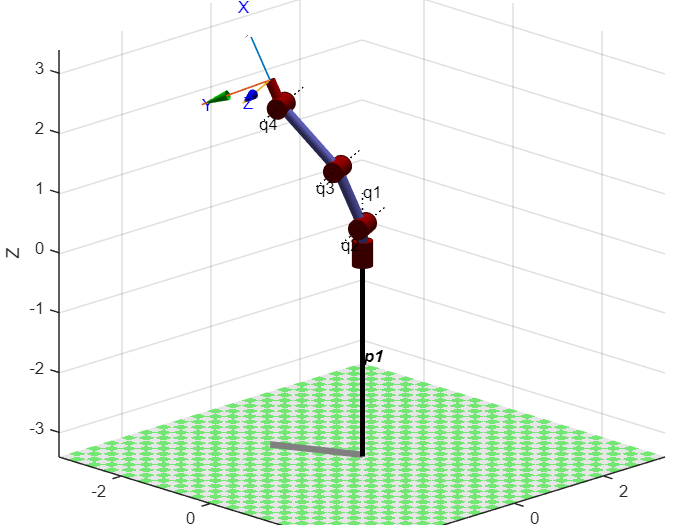


figure()
title('$$q=[25 ,25,20,-20]$$',...
'interpreter','latex','fontSize',11)
M2_2.plot(q1,'jaxes','linkcolor',[0.5 0.5 1])
view([45 18])

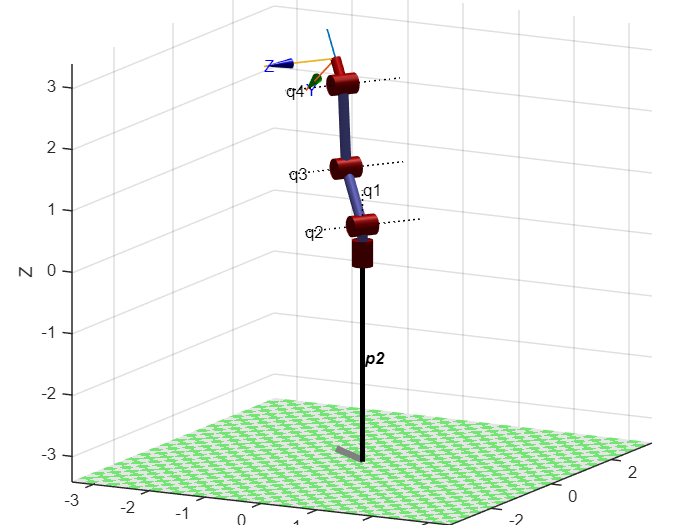


figure()
title('$$q=[-35, 35, -30, 30]$$','interpreter','latex','fontSize',11)
M2_3.plot(q2,'jaxes','linkcolor',[0.5 0.5 1])
view([28.17 12.72])

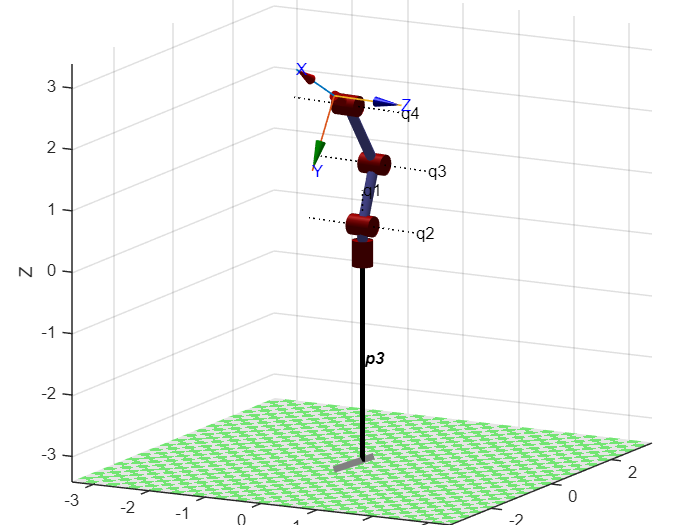


figure()
title('$$q=[-35, 35, -30 30]$$',...
'interpreter','latex','fontSize',11)
M2_4.plot(q3,'jaxes','linkcolor',[0.5 0.5 1])
view([28.17 12.72])

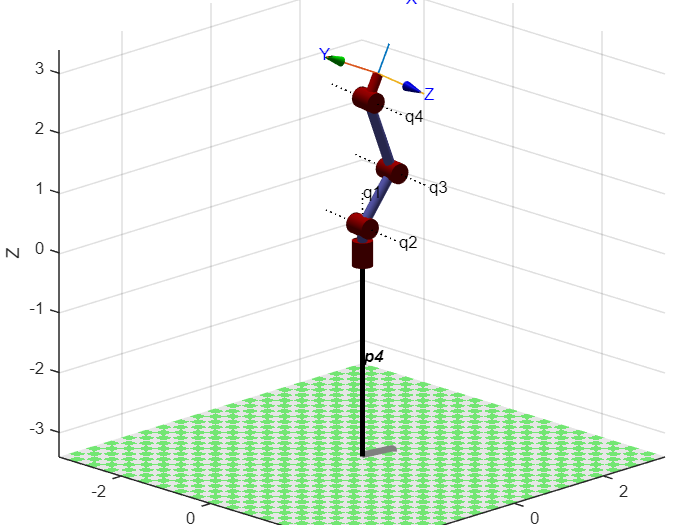


figure()
title('$$q=[80, -35, 55, -45]$$',...
'interpreter','latex','fontSize',11)
M2_5.plot(q4,'jaxes','linkcolor',[0.5 0.5 1])
view([45 18])